#  MAIN_EXP_3D_REST_PROP: Restoration experiments

 This script performs the volumetric restoration on real data

 The results are stored in folder "../results" as follows:

    exp_restore_yyyy-MM-dd-HH-mm.mat

-  vObs: observed signals

-  uEst: the obtained refractive index distribution

-  rEst: The obtained reflectance distribution

-  options: Configuration file for the restoration

 Requirements: MATLAB R2020b

 Reference:

-  Ruiki Kobayashi, Genki Fujii, Yuta Yoshida, Takeru Ota, Fumiaki Nin,  Hiroshi Hibino, Samuel Choi, Shunsuke Ono, and Shogo Muramatsu,  "Sparsity-Aware OCT Volumetric Data Restoration Using an Optical Synthesis Model,"  submitted to IEEE Trans. on Computational Imaging,  2022 

-  Genki Fujii, Yuta Yoshida, Shogo Muramatsu, Shunsuke Ono, Samuel Choi, Takeru Ota, Fumiaki Nin, and Hiroshi Hibino, "OCT Volumetric Data Restoration with Latent Distribution of Refractive Index," in Proceedings of International Conference on Image Processing, (ICIP), pp. 764–768, Sept. 2019.

 Copyright (c) 2021-2022, Ruiki KOBAYASHI and Shogo MURAMATSU

 All rights reserved.

 Contact address: Shogo MURAMATSU,

    Faculty of Engineering, Niigata University,

    8050 2-no-cho Ikarashi, Nishi-ku,

    Niigata, 950-2181, JAPAN

    http://msiplab.eng.niigata-u.ac.jp/

## Restoration setting

isMedFiltAve = true; % Preprocessing w/ median filtering
nLevels = 2;
splitfactor = []; % Split factor for OLA/OLS methods
padsize = 2^(nLevels-1)*ones(1,3); % Pad size for OLA/OLS methods
isintegritytest = false; % Integrity test for OLA/OLS methods
useparallel = false; % Parallel process with OLA/OLS methods
usegpu = ~true; % Flag for GPU
issingle = true;
method = 'udht'; % Undecimated Haar transform dictionary
maxIter = 1000;


## Display parameter

isVerbose  = ~true;
isVisible  = true;
monint     = 100;
texture    = '2D';
slicePlane = 'YZ';
daspectr   = [2 1 1];
obsScale =  1;
estScale = 1;
vdpScale = [1 10];

## Restoration parameters

factorlambda = 6e4;
factoreta = 6e4;

sizecomp = false;
%barlambda  = factorlambda*(878.3)^2*(5000/300)*2.51e-3  % 0.013653*(878.3/4)^2 = 798
barlambda = factorlambda*2.51e-3

barlambda = 150.6000

%bareta     = factoreta*(878.3)^2*(5000/300)*1.26e-2 % 0.002048*(878.3/4)^2 = 100
bareta = factoreta*1.26e-2

bareta = 756

vrange  = [1.00 1.50];

% PHIMODE in { 'Linear', 'Signed-Quadratic', 'Reflection' }
phiMode   = 'Linear';
%phiMode   = 'Signed-Quadratic';
%phiMode   = 'Reflection';

## Waveform setting

%load('../data/materials/theta'); % TODO
dtwv = "2022-04-15-15-47";
S = load("../data/materials/exp_wave_"+dtwv+"/glass_exp","theta");
theta = S.theta

theta =   878.3231
    0.2690
   31.5784
    0.2149
    0.0494


pScale = theta(1);
pSigmaxy = theta(2);
pSigma = theta(3);
pFreq  = theta(4);
pSinc  = theta(5);

## Dictionary setting

try
    if strcmp(method,'udht')
        import saivdr.dictionary.udhaar.*
        import saivdr.restoration.denoiser.*
        fwdDic = UdHaarSynthesis3dSystem();
        adjDic = UdHaarAnalysis3dSystem('NumberOfLevels',nLevels);
        gdnFcnG = GaussianDenoiserSfth();
        gdnFcnH = GaussianDenoiserSfth();
    else
        error('METHOD')
    end
catch
    error('Try SETUP')
end

## Observation

S = load('../data/materials/mouse');
aObs = S.A;
clear S;


% Bias removal
nLen = 21;
lpf = ones(nLen,1)/nLen;
lpf = permute(lpf,[2 3 1]);
sbvObs = aObs - imfilter(aObs,lpf,'symmetric');
[obsy,obsx,obsz] = size(sbvObs);


% Estimate frequency deviation
len = 100;
div = 100;
stsize = div-round(len/obsz*div)+1;
win = hamming(len,'periodic');
freq = zeros(stsize,1);
mval = zeros(stsize,1);
for i = 1:obsx
    for j = 1:obsy
        s = abs(stft(squeeze(sbvObs(i,j,:)),'Window',win,'OverlapLength',len-obsz/div,'FFTLength',2048)); 
        [val,index] = max(s(end/2+1:end,:));
        freq = freq+index(:); % Corresponds to mean of max freq at each depth
        mval = mval+val(:);
    end
end

th = 0.5;
idcs = find(mval>th*max(mval,[],'all'));
%plot(idcs,mval(idcs),'o')
%plot(idcs,freq(idcs),'o')
p = polyfit(idcs,freq(idcs),1);
imin = min(idcs);
imax = max(idcs);
dc = polyval(p,imin:imin+div-1);
depthEst = dc(end)/dc(1);
disp(depthEst)

    1.1304



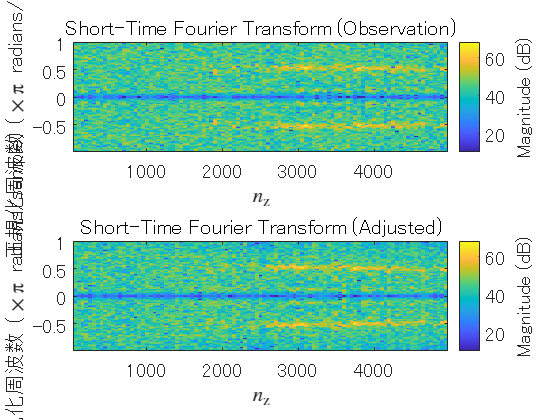


% Self sampling adjustment
funcEst = linspace(depthEst,1,obsz);
for i = 2:obsz
    funcEst(i) = funcEst(i-1) + 1/funcEst(i);
end
vObs = support.fcn_resampling(sbvObs,funcEst,0);
if isVisible
    hfig = figure(1);
    config_.len = 100;
    config_.div = 100;
    config_.win = hamming(config_.len,'periodic');
    config_.obsz = obsz;
    subplot(2,1,1)
    fcn_stftview_(hfig,sbvObs(32,32,:),"Observation",config_)
    subplot(2,1,2)
    fcn_stftview_(hfig,vObs(32,32,:),"Adjusted",config_)
    drawnow
end

%clear sbvObs

% Data store
dt = char(datetime('now','TimeZone','local','Format','yyyy-MM-dd-HH-mm'));
targetdir = "../results/exp_restore_" + dt;
if exist(targetdir,'dir') ~= 7
    mkdir(targetdir)
end


## Measurement process

msrProc = support.Coherence3d(...
    'Scale',pScale,...
    'Sigma',pSigma,...
    'Frequency',pFreq,...
    'Sinc',pSinc,...
    'Sigmaxy',pSigmaxy);

pKernel = msrProc.Kernel;

## Display observation

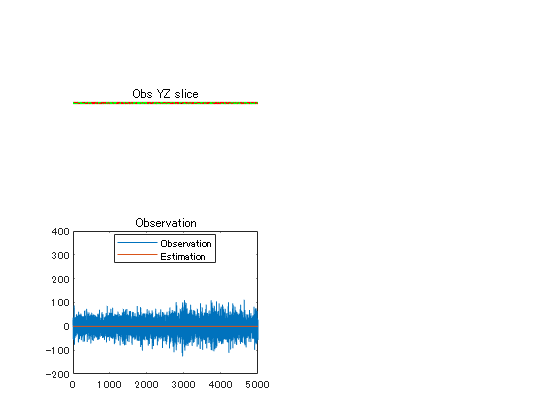

if isVisible
    import saivdr.utility.*

    hImg = figure(2);
    subplot(2,2,1)
    vdvobs = VolumetricDataVisualizer(...
        'Texture',texture,...
        'VRange',[-1 1],...
        'Scale',obsScale);
    if strcmp(texture,'2D')
        vdvobs.SlicePlane = slicePlane;
        vdvobs.step(vObs);
        title(sprintf('Obs %s slice',slicePlane))
    else
        vdvobs.DAspect = daspectr;
        vdvobs.step(vObs);
        title('Obs volume')
    end
    %
    subplot(2,2,3)
    vdpobs = VolumetricDataPlot('Direction','Z','NumPlots',2);
    vdpobs.step(gather(vObs),zeros(size(vObs)));
    axis([0 size(vObs,3) -2e2 4e2])
    legend('Observation','Estimation','Location','best')
    title('Observation')
end

## Preparation for monitoring

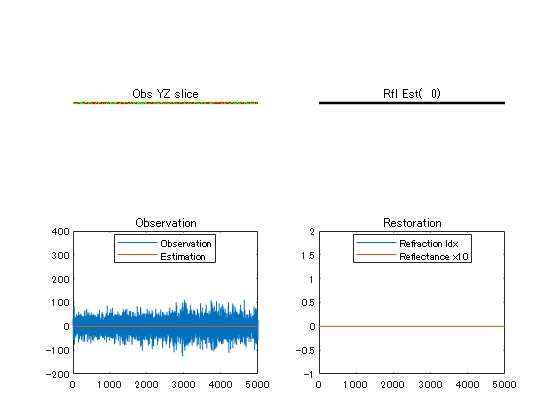

if isVisible
    import saivdr.utility.*
    vdv = VolumetricDataVisualizer(...
        'Texture',texture,...
        'VRange',[-1 1],...
        'Scale',estScale);
    if strcmp(texture,'2D')
        vdv.SlicePlane = slicePlane;
    else
        vdv.DAspect = daspectr;
    end
    phiapx = support.RefractIdx2Reflect(...
        'PhiMode',phiMode,...
        'VRange', vrange);
    r = phiapx.step(zeros(size(vObs)));
    %
    figure(hImg)
    subplot(2,2,2)
    vdv.step(r);
    hTitle2 = title('Rfl Est(  0)');
    %
    subplot(2,2,4)
    vdp = VolumetricDataPlot('Direction','Z','Scales',vdpScale,'NumPlots',2);
    vdp.step(zeros(size(vObs)),r);
    axis([0 size(vObs,3) -1 2])
    legend('Refraction Idx',['Reflectance x' num2str(vdpScale(2))],'Location','best')
    title('Restoration')
end

## Stage 1 median filtering

if isMedFiltAve
   vObs = support.fcn_medfilt1ave(vObs);
end

## Verbose setting

if isVerbose
    [obsy,obsx,obsz]=size(vObs);
    disp('-------------------------------')
    disp('Data size')
    disp('-------------------------------')
    disp(['Width × Height × Depth     : ' num2str(obsy) 'x' num2str(obsx) 'x' num2str(obsz)])
    disp('-------------------------------')
    disp('Observation model')
    disp('-------------------------------')
    disp(['Scale                      : ' num2str(pScale)])
    disp(['Sigma for depth            : ' num2str(pSigma)])
    disp(['Sigma for width and height : ' num2str(pSigmaxy)])
    disp(['Angular frequency          : ' num2str(2*pi*pFreq)])
    disp(['Bp for Sinc                : ' num2str(pSinc)])
    disp(['Frequency fluctuation      : ' num2str(depthEst)])
    disp('-------------------------------')
    disp(['Pre-proc. w/ median filter : ' num2str(isMedFiltAve)])
end

## Gamma1 calculation

Lipschitz constant for the gradient of the fidelity term assuming a Parseval tight dictionary

d_ = zeros(size(vObs));
d_(floor(end/2),floor(end/2),floor(end/2)) = 1; % 3-D impulse signal
dltFcn = support.Sobel3d('KernelMode','Normal');
h_ = msrProc.step(dltFcn.step(d_),'Forward');
beta1_ = @(x) 2*abs(x(2)-x(1))/(x(2)+x(1))^2;
mu = beta1_(vrange).^2*max(abs(fftn(h_)).^2,[],'all');
% Gamma1 
gamma1 = 2/(1.05*mu);
disp("gamma1 = " + num2str(gamma1))

gamma1 = 8.8641e-07


## Instantiation of restoration system

if issingle
    vObs = single(vObs);
end
if usegpu
    vObs = gpuArray(vObs);
end

pdshshc = support.PdsHsHcOct3(...
    'Observation',    vObs,...
    'Lambda',         barlambda,...
    'Eta',            bareta,...
    'IsSizeCompensation', sizecomp,...
    'Beta',           mu,...
    'Gamma1',         gamma1,...
    'PhiMode',        phiMode,...
    'VRange',         vrange,...
    'MeasureProcess', msrProc,...
    'Dictionary',     { fwdDic, adjDic },...
    'GaussianDenoiser', { gdnFcnG, gdnFcnH } ,...
    'SplitFactor',    splitfactor,...
    'PadSize',        padsize,...
    'UseParallel',    useparallel,...
    'UseGpu',         usegpu,...
    'IsIntegrityTest', isintegritytest);

disp(pdshshc)

  support.PdsHsHcOct3 のプロパティ:

           Observation: [64×64×5000 single]
                Lambda: 175.7000
                   Eta: 882
                Gamma1: 8.8641e-07
                Gamma2: 2.5582e+04
                  Beta: 2.1489e+06
                VRange: [1 1.5000]
               PhiMode: 'Linear'
        MeasureProcess: [1×1 support.Coherence3d]
            Dictionary: {1×2 cell}
      GaussianDenoiser: {1×2 cell}
           SplitFactor: []
               PadSize: [2 2 2]
                Result: []
     LambdaCompensated: []
        EtaCompensated: []
       IsIntegrityTest: false
    IsSizeCompensation: false
           UseParallel: false
                UseGpu: false



## Restoration process

経過時間は 7.965731 秒です。
経過時間は 4.926116 秒です。
経過時間は 4.931758 秒です。
経過時間は 4.992428 秒です。
経過時間は 4.922870 秒です。
経過時間は 4.927942 秒です。
経過時間は 4.962918 秒です。
経過時間は 5.017198 秒です。
経過時間は 4.916099 秒です。
経過時間は 4.864172 秒です。
経過時間は 4.837256 秒です。
経過時間は 4.860944 秒です。
経過時間は 4.900446 秒です。
経過時間は 4.908989 秒です。
経過時間は 4.962081 秒です。
経過時間は 4.946776 秒です。
経過時間は 4.948307 秒です。
経過時間は 5.010009 秒です。
経過時間は 4.952004 秒です。
経過時間は 4.996403 秒です。
経過時間は 5.025764 秒です。
経過時間は 4.927656 秒です。
経過時間は 4.959928 秒です。
経過時間は 4.978718 秒です。
経過時間は 4.968060 秒です。
経過時間は 4.968759 秒です。
経過時間は 4.877920 秒です。
経過時間は 4.852878 秒です。
経過時間は 4.821725 秒です。
経過時間は 4.900066 秒です。
経過時間は 4.911538 秒です。
経過時間は 4.915126 秒です。
経過時間は 4.892151 秒です。
経過時間は 4.904349 秒です。
経過時間は 4.937237 秒です。
経過時間は 4.915422 秒です。
経過時間は 4.857608 秒です。
経過時間は 4.833221 秒です。
経過時間は 4.815634 秒です。
経過時間は 4.862216 秒です。
経過時間は 4.856011 秒です。
経過時間は 4.889056 秒です。
経過時間は 4.943368 秒です。
経過時間は 4.884024 秒です。
経過時間は 4.825715 秒です。
経過時間は 4.814384 秒です。
経過時間は 4.865874 秒です。
経過時間は 4.904724 秒です。
経過時間は 4.906033 秒です。
経過時間は 4.917724 秒です。


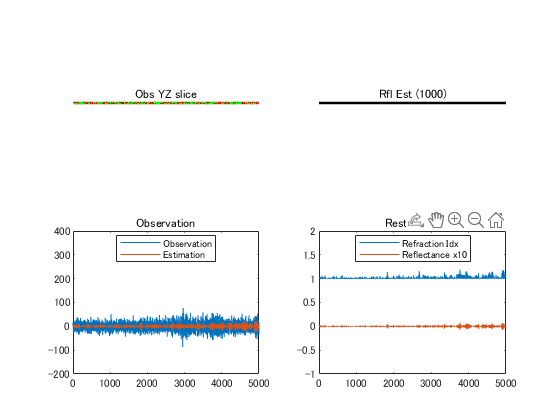

経過時間は 5.402509 秒です。


id = 'mouse';
for itr = 1:maxIter
    tic
    uEst = pdshshc.step();
    if isVerbose && itr==1
        lambda = pdshshc.LambdaCompensated;
        eta   = pdshshc.EtaCompensated;
        disp(['lambda = ' num2str(lambda)]);
        disp(['eta    = ' num2str(eta)]);
    end
    % Monitoring
    if isVisible && (itr==1 || mod(itr,monint)==0)
        rEst = gather(phiapx.step(uEst));
        vdv.step(rEst);
        vdpobs.step(gather(vObs),msrProc((rEst),'Forward'));
        vdp.step(gather(uEst),rEst);
        set(hTitle2,'String',sprintf('Rfl Est (%3d)',itr));
        drawnow
    end
    toc
end

lambda = pdshshc.LambdaCompensated;
eta   = pdshshc.EtaCompensated;
disp(['lambda = ' num2str(lambda)]);

lambda = 175.7


disp(['eta    = ' num2str(eta)]);

eta    = 882


## Store results

targetdir

targetdir = "./results/exp_restore_2022-04-16-19-56"

options.method = method;
options.barlambda = barlambda;
options.bareta    = bareta;
options.lambda = lambda;
options.eta    = eta;
options.gamma1 = gamma1;
options.phiMode = phiMode;
options.vrange = vrange;
options.msrProc = msrProc;
options.fwdDic = fwdDic;
options.adjDic = adjDic;
options.gdnFcnG = gdnFcnG;
options.gdnFcnH = gdnFcnH;
options.depthEst = depthEst;
save(targetdir+"/rest_exp_" +id,'uEst','rEst','options','vObs','aObs','sbvObs','factorlambda','factoreta')



## Functions for visualization

function fcn_stftview_(hfig,array3d,signalname,config)
win = config.win;
len = config.len;
obsz = config.obsz;
div = config.div;
figure(hfig)
stft(squeeze(array3d(1,1,:)),'Window',win,'OverlapLength',len-obsz/div,'FFTLength',2048);
%ylabel("Normalized Frequency ($\times\pi$ radians/sample)","Interpreter","latex")
xlabel("$n_\mathrm{z}$", "Interpreter","latex")
title("Short-Time Fourier Transform ("+signalname+")")
caxis([10 68])
yticks(-1:0.5:1)
%
hcb = hfig.Children(1);
hcb.Label.String =  "Magnitude (dB)";
hcb.FontSize = 14;
hax = hfig.Children(2);
hax.FontSize = 14;
end